# High Voltage Battery - Test Case

## Charge

mdl = "BatteryHV_harness_model";
load_system(mdl)

% Load model parameters.
BatteryHV_harness_setup

% Select battery model.
BatteryHV_useRefsub_Basic

Model: BatteryHV_harness_model
Setting up referenced subsystem: BatteryHV_refsub_Basic



% Setup simulation case.
BatteryHV_selectSimulationCase_Charge( ...
  CRate = -1, ...  Negative value for charge
  StateOfCharge_pct = 0 )

Setting up simulation...
Simulation case: Charge battery
Setting simulation stop time to 3600 sec.
Setting block parameters for input blocks...
Setting initial conditions...
initial.hvBattery_SOC_pct = 0
initial.hvBattery_Charge_Ahr = 0
initial.hvBattery_Temperature_K = 293.15


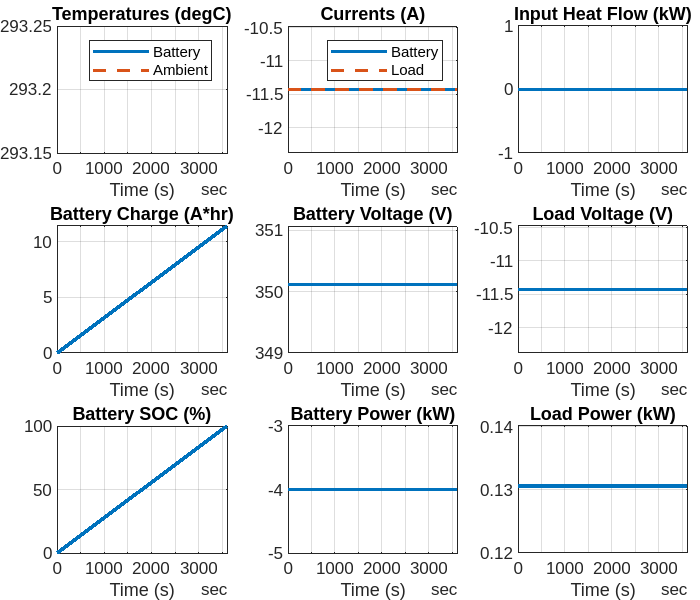


% ambient.temp_K =  273.15 + inpData.Options.InitialTemperature_degC;
% initial.hvBattery_Temperature_K = ambient.temp_K;

% Run simulation.
simOut = sim(mdl);

% Collect logged signals and visualize.
% The basic version of the battery block does not simulate battery temperature.
logged_signals = extractTimetable(simOut.logsout);
BatteryHV_plotResults(logged_signals);

*Copyright 2020-2022 The Mathworks, Inc.*